# Característiques locals IV

## Detecció per Viola Jones

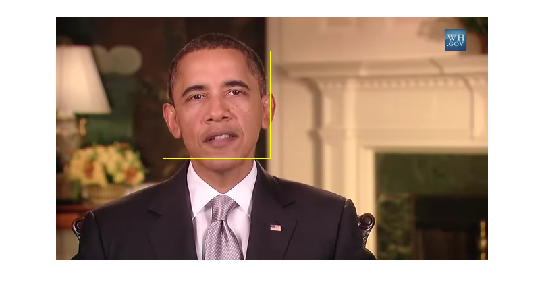

Detector = vision.CascadeObjectDetector("FrontalFaceCART");
EyesDetector = vision.CascadeObjectDetector("EyePairBig");
video = VideoReader("obama.webm");
video.CurrentTime = 2;
frames = 50;
while hasFrame(video) && frames > 0
    VideoFrame = readFrame(video);
    bboxes = step(Detector, VideoFrame);
    bboxesEyes = step(EyesDetector, VideoFrame);
    for i = 1:4:size(bboxes)
        for j = 1:4:size(bboxesEyes)
            if (bboxesEyes(j) > bboxes(i) && bboxesEyes(j+1) > bboxes(i+1) && bboxesEyes(j+2) < bboxes(i+2) && bboxesEyes(j+3) < bboxes(i+3))
                VideoFrame = insertShape(VideoFrame,'Rectangle', bboxes(i:i+3));
            end
        end
    end
    imshow(VideoFrame);
    drawnow;
    frames = frames - 1;
end

## Detecció per Viola Jones i Swift

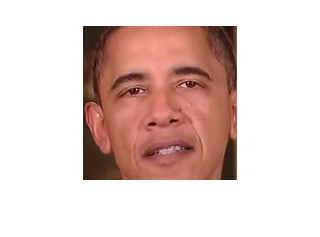

Detector = vision.CascadeObjectDetector("FrontalFaceCART");
EyesDetector = vision.CascadeObjectDetector("EyePairBig");
video = VideoReader("obama.webm");
video.CurrentTime = 2;

VideoFrame = readFrame(video);
bboxes = step(Detector, VideoFrame);
bboxesEyes = step(EyesDetector, VideoFrame);
for i = 1:4:size(bboxes)
    for j = 1:4:size(bboxesEyes)
        if (bboxesEyes(j) > bboxes(i) && bboxesEyes(j+1) > bboxes(i+1) && bboxesEyes(j+2) < bboxes(i+2) && bboxesEyes(j+3) < bboxes(i+3))
            %VideoFrame = insertShape(VideoFrame,'Rectangle', bboxes(i:i+3));
            im_obj = imcrop(VideoFrame, bboxes(i:i+3));
        end
    end
end

imshow(im_obj);

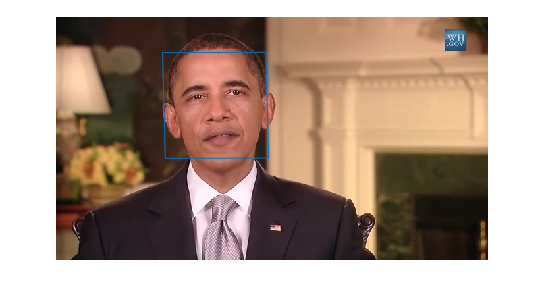

im_obj_gray = rgb2gray(im_obj);
kp_obj = detectSIFTFeatures(im_obj_gray);
[feat_obj, kp_obj] = extractFeatures(im_obj_gray,kp_obj);

frames = 50;
while hasFrame(video) && frames > 0
    im_esc = readFrame(video);
    im_esc_gray = rgb2gray(im_esc);
    kp_esc = detectSIFTFeatures(im_esc_gray);

    [feat_esc, kp_esc] = extractFeatures(im_esc_gray,kp_esc);

    pairs = matchFeatures(feat_obj,feat_esc,'MatchThreshold',10);
    best_kp_obj = kp_obj(pairs(:,1),:);
    best_kp_esc = kp_esc(pairs(:,2),:);

    [T] = estimateGeometricTransform2D(best_kp_obj,best_kp_esc,'affine');
    [fo,co] = size(im_obj_gray);
    [fe,ce] = size(im_esc_gray);
    box = [1,1; co,1; co,fo; 1,fo; 1,1];

    nbox = transformPointsForward(T,box);
    imshow(im_esc);
    hold on
    line(nbox(:,1),nbox(:,2));
    %hold off
    drawnow;
    frames = frames - 1;
end